# Simulating complete PPG circuit

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

Dependencies include files rescale1.m, plethy.mat and ppg2.slx

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter6/PPG'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Data generation

% Generate Data
clear all
load('plethy.mat');
a1=rescale1([a;a;a;a;a;a;a;a;a;a]);
a2=0.05*(1-0.01*a1);
T=0.0001;
len=10*1/T+1;
step=floor((1/T)/1000); %1kHz
%a2q(1:step:step*length(a2))=a2;
a2q1 = interp1(1/length(a):1/length(a):10,a1,0:T:10, 'linear','extrap');
Pulse(:,1)=0:T:10; %time
Pulse(:,2)=a2q1; % irradiance
Vin(:,1)=0:T:10; %time;
Vin(:,2)=1;
Airgap(:,1)=0:T:10; %time;
Airgap(1:end,2)=0.01;
T_SH = 0.006;

## Simulation

% Running simulation
simOut = sim('spo2_whole2', 'CaptureErrors', 'on');
% Setting parameters
%save('PPG_whole.mat','simOut')

## Plotting

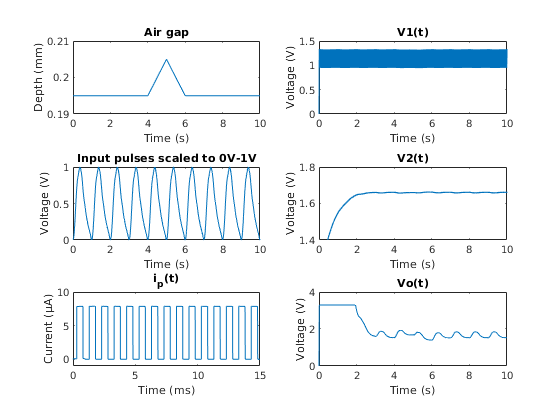

%load('PPG_whole.mat');
figure
subplot(3,2,5)
plot(simOut.v_out.Time*1e3, -simOut.i_out.Data*1e6)
xlim([0,15])
ylim([-1,10])
xlabel('Time (ms)', 'FontSize', 10)
title('i_p(t)')
ylabel('Current (µA)', 'FontSize', 10)

subplot(3,2,2),plot(simOut.v_out.Time, simOut.v_out.Data)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title('V1(t)')
xlim([0,10])


subplot(3,2,4),plot(simOut.v_out.Time, simOut.v_out1.Data)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title('V2(t)')
xlim([0,10])
ylim([1.4,1.8])

subplot(3,2,6),plot(simOut.v_out.Time, simOut.v_out2.Data)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title('Vo(t)')
xlim([0,10])


subplot(3,2,3),plot(Pulse(:,1), Pulse(:,2))
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title('Input pulses scaled to 0V-1V')
ylim([0,1])

subplot(3,2,1),plot(Airgap(:,1), Airgap(:,2))
xlabel('Time (s)', 'FontSize', 10)
ylabel('Depth (mm)', 'FontSize', 10)
title('Air gap')
ylim([0.19,0.21])


exportgraphics(gcf,"Fig6.16.jpg", 'Resolution',600)